# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', ['Mouse5_Day3'], ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional

nwb =   NwbFile with properties:

                                             nwb_version: '2.5.0'
                                        file_create_date: []
                         general_source_script_file_name: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: 2018-04-25T02:30:03.000000-04:00
                               timestamps_reference_time: []
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
               

nwb

## Extracellular electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in a `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrode table

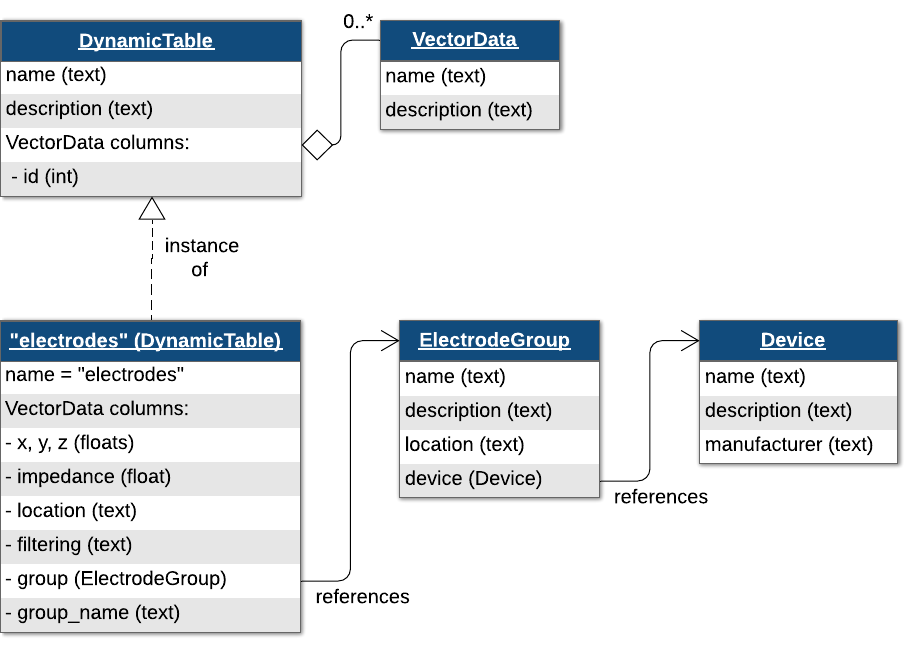

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

nshanks = 4;
nchannels_per_shank = 3;
variables = {'x', 'y', 'z', 'imp', 'location', 'filtering', 'group', 'label'};
tbl = cell2table(cell(0, length(variables)), 'VariableNames', variables);
device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', device);
for ishank = 1:nshanks
    electrode_group = types.core.ElectrodeGroup( ...
        'description', ['electrode group for shank' num2str(ishank)], ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    nwb.general_extracellular_ephys.set(['shank' num2str(ishank)], electrode_group);
    group_object_view = types.untyped.ObjectView(electrode_group);
    for ielec = 1:nchannels_per_shank
        electrode_label = ['shank' num2str(ishank) 'elec' num2str(ielec)];
        tbl = [...
            tbl; ...
            {5.3, 1.5, 8.5, NaN, 'unknown', 'unknown', group_object_view, electrode_label} ...
        ];
    end
end
tbl

tbl = 12×8 table
     x      y      z     imp     location       filtering                group                     label     
    ___    ___    ___    ___    ___________    ___________    ____________________________    _______________

    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec1'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec2'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec3'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2elec1'}
    5.3    1.5    8.5    NaN    {'unknown'}    {'u

electrode_table = util.table2nwb(tbl, 'all electrodes');
nwb.general_extracellular_ephys_electrodes = electrode_table;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrode_table), ...
    'description', 'all electrodes', ...
    'data', (0:height(tbl)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

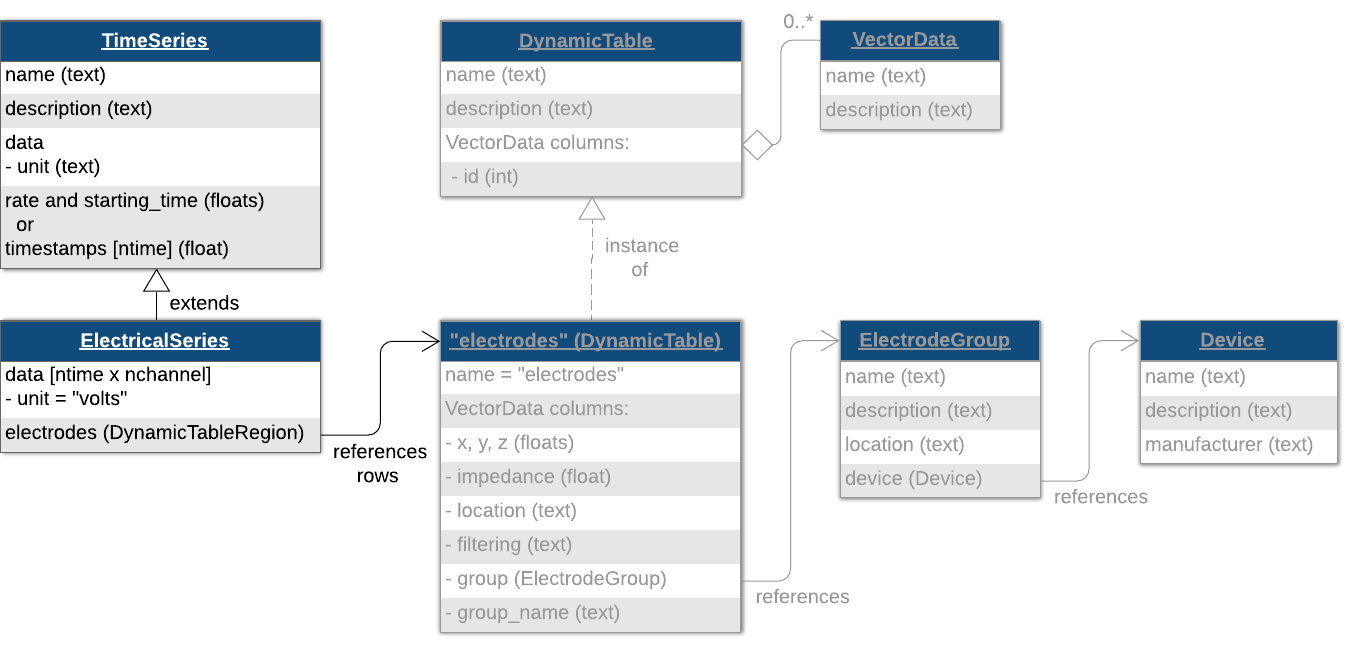

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

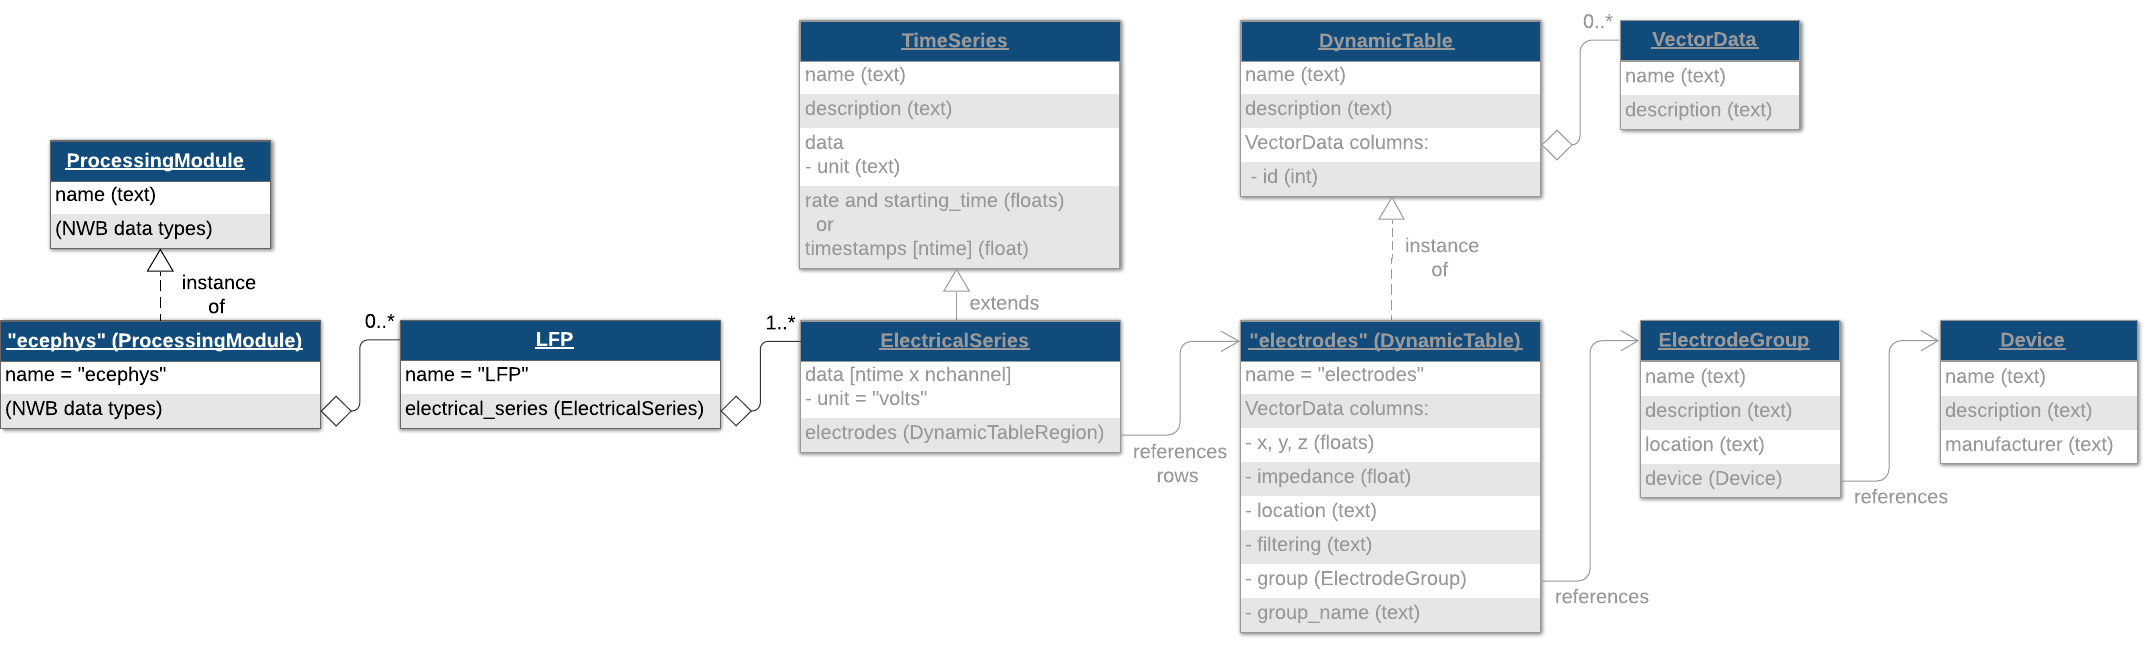

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike times

#### Ragged arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for ishank = 1:num_cells
    spikes{ishank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.6501 0.3082 0.2028 0.9918 0.8831 0.4310 0.0796 0.8529 0.9656 0.1383 0.5499 0.4954 0.3379 0.7157 0.6034 0.9434 0.3359]}    {[0.1022 0.8595 0.3883 0.8858 0.1116 0.5729 0.9346 0.8943 0.7162 0.2945 0.2053 0.1538 0.9878 0.0250 0.9661 0.2611 0.3737 0.8830]}    {[0.7425 0.3015 0.5056 0.5389 0.4820 0.1673 0.0619 0.6462 0.5480 0.6662 0.3867 0.4777 0.9175 0.3144 0.6887 0.4303]}    {[0.4030 0.9835 0.9202 0.3676 0.6018 0.6007 0.5672 0.4622 0.8927 0.6612 0.8715 0.0910 0.3742 0.7480 0.0466 0.8924 0.7931 0.3336 0.2076 0.2791 0.3655]}    {[0.1897 0.1430 0.7543 0.6925 0.8328 0.1597 0.5024 0.5733 0.2402 0.1321 0.2898 0.6036 0.2626 0.7171 0.2318 0.5479 0.1714 0.5278 0.0503 0.9576 0.5815 0.4523 0.6443 0.8547 0.9910]}    {[0.7494 0.6014 0.7241 0.3767 0.2110 0.7667 0.9864 0.2787 0.5326 0.3088 0.3465 0.5762 0.2979 0.7514 0.1276 0.1696 0.1418 0.6786 0.7916 0.8569 0.4234 0.6390 0.9831 0.5120 0.6763 0.6406 0.5578]}    {[0.4848 0.6270 0.8020 0.1106 0.3906 0.3991 0.2204 0.0908 0.5

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

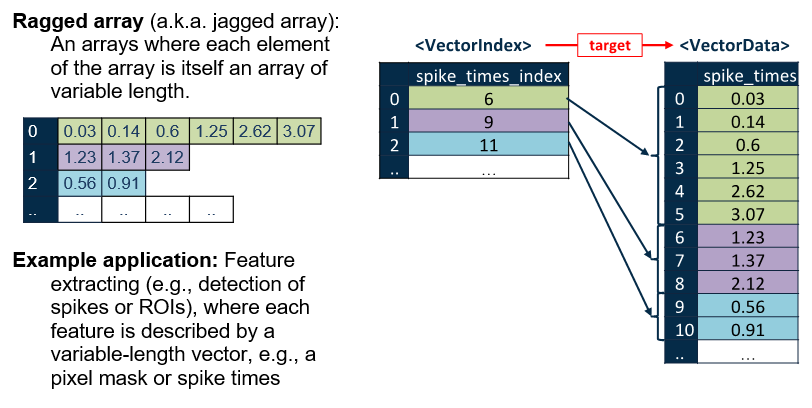

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(0:length(spikes) - 1) ...
    ), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Write the file

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing data regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =     0.5938   -0.4753   -0.5075    0.3021   -0.2914    0.0077    1.2020    0.0749    0.6444    0.0383
    0.0893    0.8383    2.0713    0.6750    0.2827    2.7530    1.1147   -0.3998    0.2750   -1.3381
   -0.2557    0.7498   -0.1889   -0.5439   -2.0241   -0.3986    0.4520   -1.0113    0.2583   -0.3130
   -0.3645   -0.1192    0.9762    0.1519    0.5527   -0.7931   -0.6456    1.4499    0.4875   -2.0865
    1.5314    1.6395    1.8022    0.8296    1.2646    1.6529   -0.2080    1.4211   -0.4894    0.4756



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.6501
    0.3082
    0.2028
    0.9918
    0.8831
    0.4310
    0.0796
    0.8529
    0.9656
    0.1383


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)